# Geographic Line Plot

Plot a line in a geographic axes with vertices at the latitude-longitude locations specified (in degrees) by the vectors `lat` and `lon`. 

### Specify Latidude and Longitude Point Pairs

Specify the endpoints of the line using the coordinates of Seattle and Anchorage. Specify latitude and longitude in degrees.

latSeattle = 47.62;
lonSeattle = -122.33;
latAnchorage = 61.20;
lonAnchorage = -149.9;
latPtBarrow = 71.38;
lonPtBarrow = -156.47;

### Basic Geoplot

Plot the data on a map. 

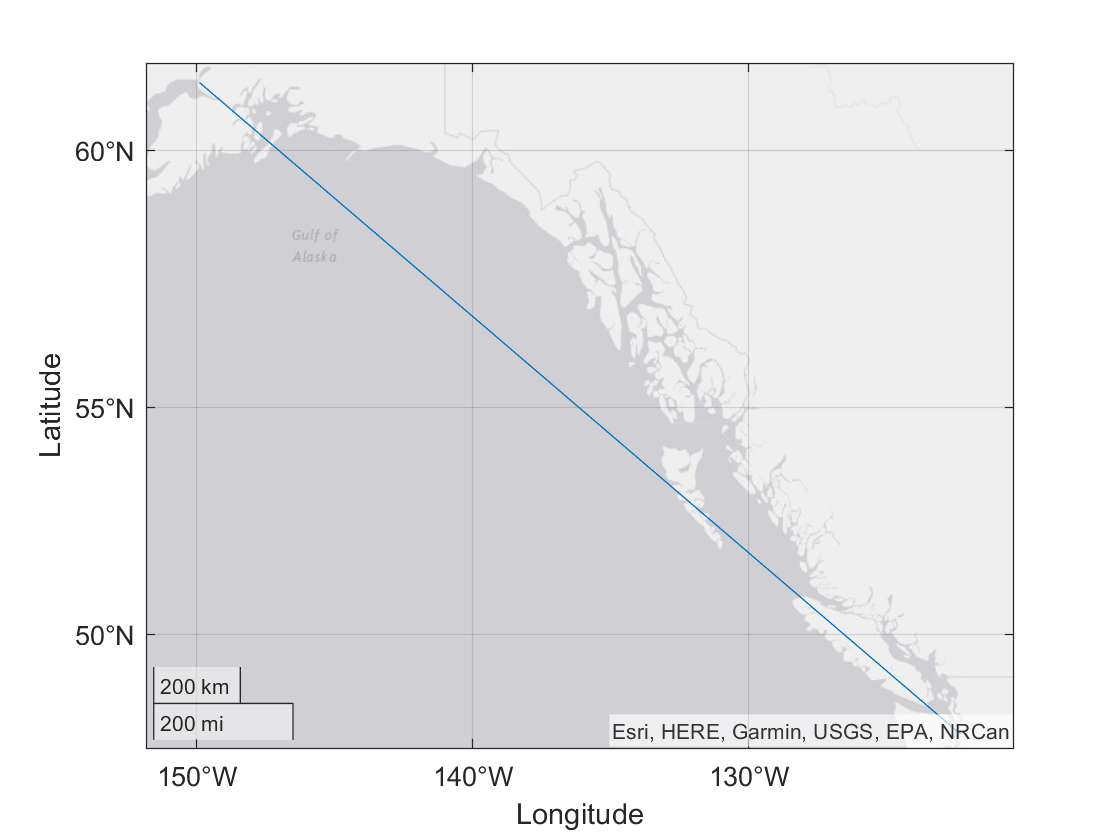

geoplot([latSeattle latAnchorage],[lonSeattle lonAnchorage])

## Customizations

### Specify Line Options 

Following the latitude-longitude point pairs, specify a line color and line style using color and line codes. To draw a blue solid line, input `"b-"` and a yellow dotted line is specified by `"y:"` Additional line features can also be specified as name-value pairs, for example, line width or color as an RGB triplet.

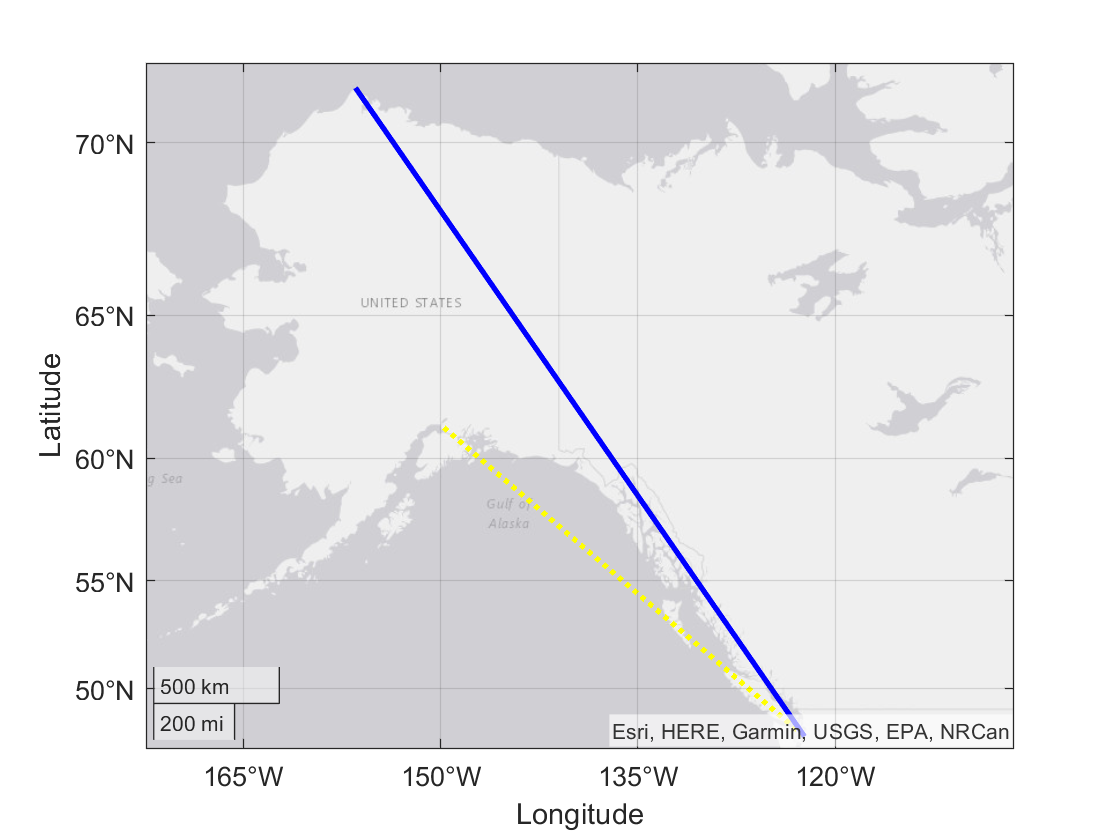

geoplot([latSeattle latAnchorage],[lonSeattle lonAnchorage],'y:',...  % Specify the line between Seattle and Anchorage as dotted yellow
    [latSeattle latPtBarrow],[lonSeattle lonPtBarrow],'b-',...        % Specify the line between Seattle and Point Barrow as solid blue
    "LineWidth",2)                                                    % Set the line thickness

### Customize the Map View

The overall view encompassed by the plot can be expanded or decreased by specifying `geolimits` as latitude longitude limits. The basemap's appearance can be changed to display color coded terrain detail.

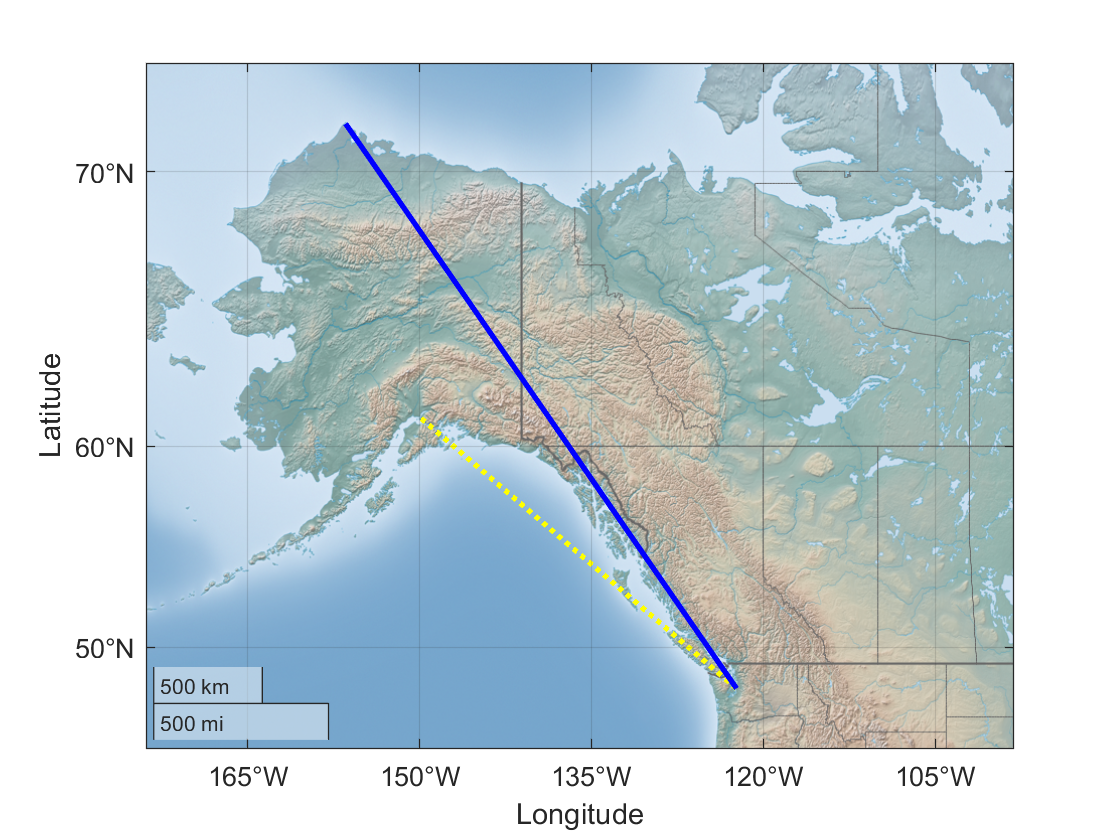

geolimits([44 73],[-149 -123])
geobasemap colorterrain

### Add Location and Names

Add text by calling the text function with the city names at each latitude and longitude location.

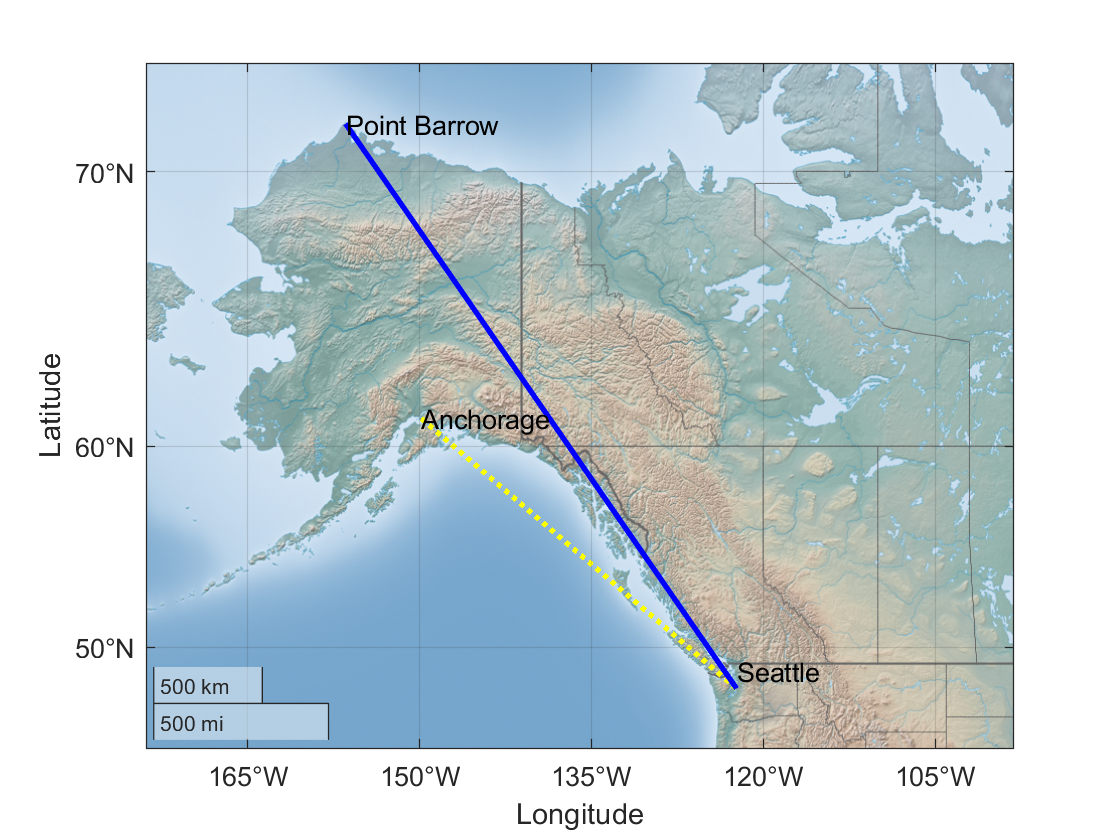

text(latAnchorage,lonAnchorage,"Anchorage");
text(latPtBarrow,lonPtBarrow,"Point Barrow");
text(latSeattle,lonSeattle,"Seattle",...
    "VerticalAlignment","bottom");

## Additional Information

### Get All Geoplot Properties

Graphics objects in MATLAB have many properties. To see all the properties of geoplot, uncomment the following code

% get(gb)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[geoplot](https://www.mathworks.com/help/matlab/ref/geoplot.html)